**Part 1: **Demonstrate your ability to plot 1D functions given a range of input parameters.

Write a commented script that produces a labelled plot over the domain -1 < x < 10 for the following functions *on the same plot axis*:

- y = exp(-kx) when x > 0, and zero otherwise.

- y = exp(-kx) sin(wx) when x > 0, and zero otherwise. Choose an pair of parameter values within 0.2 < k < 0.5 and 2 < w < 5.

Your plot should be labelled to include any parameter values, and ideally your code will automatically handle *arbitrary* values of these parameters.

The functions should be plotted with distinct line-styles.

clc
clear

% Define parameters
k = 0.2 + rand(1) * 0.3;
w = 2 + rand(1) * 3;
x = (-10:100);

% Algorithm
y1 = nan(length(x));
y2 = nan(length(x));

for i = 1:length(x)
    if x(i) > 0
        y1(i) = exp(-k .* x(i));
        y2(i) = exp(-k .* x(i)) * sin(w .* x(i));
    else
        y1(i) = 0;
        y2(i) = 0;
    end
end

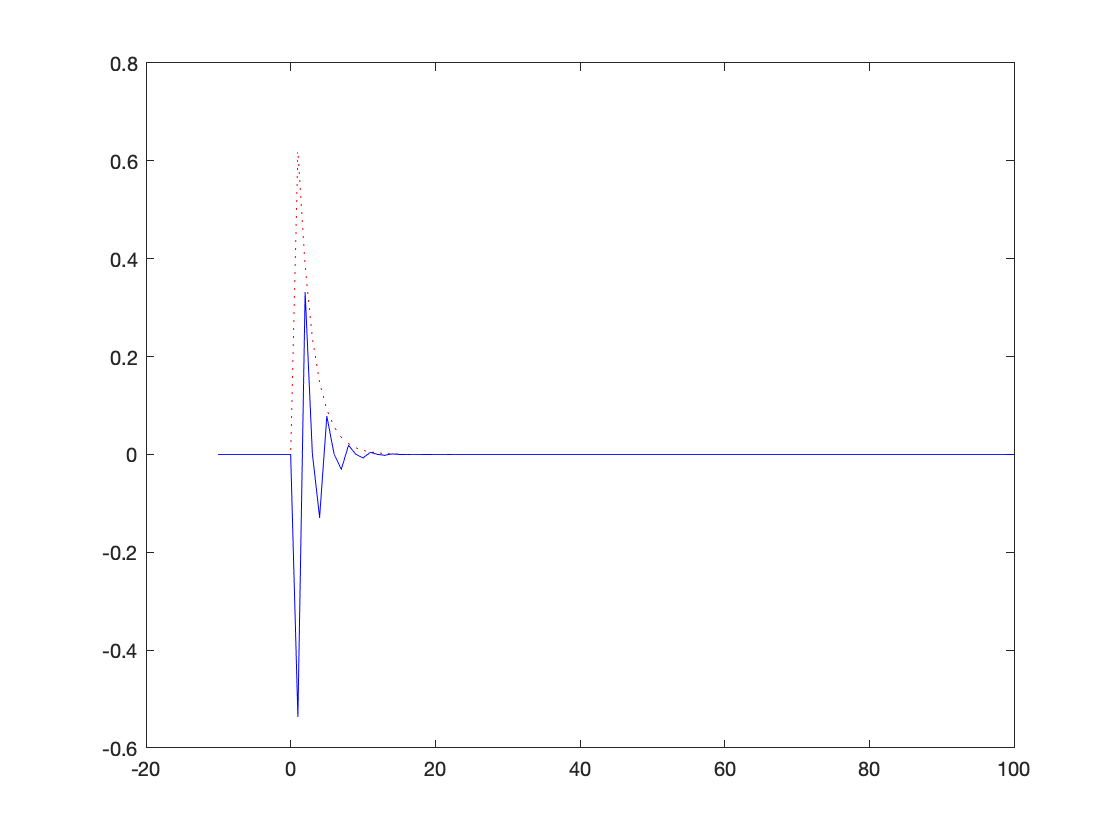

% Plot both functions with distinct line-styles
plot(x, y1, "r:");
hold on;
plot(x, y2, "b-");
hold off;

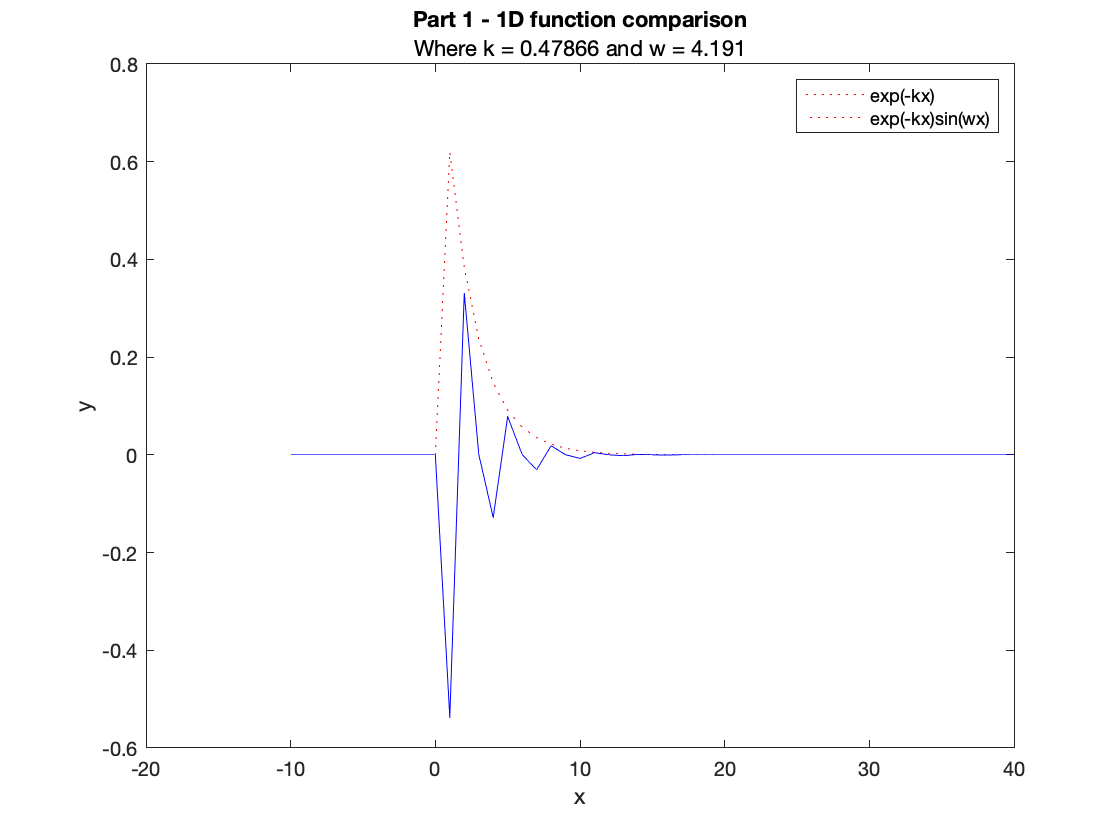

% Decorate graph
title("Part 1 - 1D function comparison");
subtitle("Where k = " + k + " and w = " + w);
xlabel("x");
ylabel("y");
legend('exp(-kx)', 'exp(-kx)sin(wx)')

% NEED TO FIX LEGEND

% Restrict graph domain
xlim([-20, 40]);